# DSP A1

## Time domain analysis

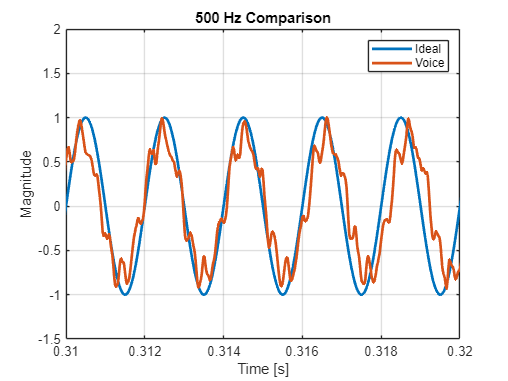

clear variables;

% Declaring some variables
fs1 = 44100; % Sampling frequency of ideal signal
T   = 0.5;   % Length of signal in seconds
f0  = 500;   % Frequency of ideal signal
am  = 1;     % Amplitude of ideal signal

% Time vector for good luck
t = 0:1/fs1:T-1/fs1;

% Need to generate a "perfect" sine wave of 500 Hz
sin500_ideal = sampleSin(fs1, T, f0, am);

% Loading my beautiful voice
[sin500_voice, fs2] = audioread('beautiful_500_Hz.wav');
% NOTE: This file has not been uploaded to Github, but if you want to use
% your own clip, it has to be encoded as a mono .wav file lasting 0.5
% seconds with a sampling rate of 44100 Hz

% Just in case the sampling rates do not match
if (fs1~=fs2)
    sin500_voice = resample(sin500_voice, fs2, fs1);
end
% NOTE: This only works with the "Signal Processing Toolbox" installed


% Normalizing so the two signals have the same amplitude
maxVol = max(sin500_voice);
sin500_voice = sin500_voice*(am/maxVol);

% Uncomment to find the place of max volume
%find(sin500_voice == max(sin500_voice))

% By reading the plot there appears to be 
% one peak at 0.314172 and another at 0.314535 
% Finding required time shift
shift_samples=floor((0.314535-0.314172)*fs1);
sin500_voice_shifted = paddata(sin500_voice(1:end-shift_samples), numel(sin500_voice), Side="leading");


% Hopefully making a pretty plot
figure(1);
p1 = plot(t, sin500_ideal);
set(p1,{'LineWidth'},{2})
hold on;
p2 = plot(t, sin500_voice_shifted);
set(p2,{'LineWidth'},{2})
hold off;
grid on;
xlim([0.31 0.32]); % The loudest part [0.31 0.32]
ylim([-1.5 2]);
title('500 Hz Comparison');
legend('Ideal','Voice');
xlabel('Time [s]');
ylabel('Magnitude');


% Uncomment for pain
%sound(sin500_ideal*0.01, fs1) % The signal is multiplied by 0.01 to make it less loud

## Making the spectra

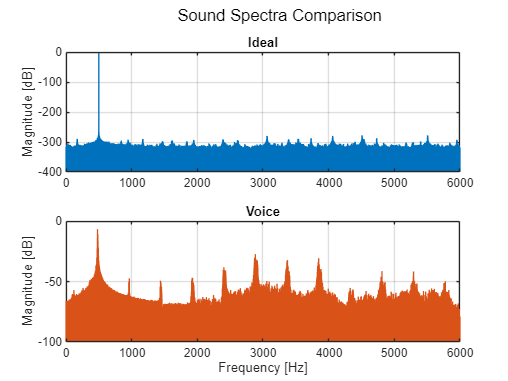

% Find spectra
[spec_ideal, freq_ideal] = make_spectrum(sin500_ideal, fs1);
[spec_voice, freq_voice] = make_spectrum(sin500_voice, fs1);

% Multiply spectra by 2, as we cut out frequencies below 0
spec_ideal = spec_ideal*2;
spec_voice = spec_voice*2;

% Convert to dB for plotting
spec_dB_ideal = 20*log10(abs(spec_ideal));
spec_dB_voice = 20*log10(abs(spec_voice));

% Hopefully making another pretty plot
% Datatips added manually after
figure(2);
subplot(2,1,1);
p3 = stem(freq_ideal(1:11025), spec_dB_ideal(1:11025),'BaseValue',-400);
set(p3,{'LineWidth','Marker'},{1,"none"})
grid on;
xlim([0 6000]);
title('Ideal');
ylabel('Magnitude [dB]');
ylim([-400 1]);

subplot(2,1,2);
p4 = stem(freq_voice(1:11025), spec_dB_voice(1:11025),'BaseValue',-100);
set(p4,{'LineWidth','Marker','Color'},{1,"none","#D95319"})
grid on;
xlim([0 6000]);
title('Voice');
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
sgtitle('           Sound Spectra Comparison'); % Big space at the front so datapoint doesn't overlap with title

%ylim([-100 0]);


